format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)
% latex(expres)

**INDSÆT I SI ENHEDER**

Sted funktion


$$s(t) = s_0 + v_0 \cdot t + a_0 \cdot \frac{t^2}{2}$$


Hastigheds funktion


$$v(t) = v_0 + a_0 \cdot t$$
 

Kan splittes op i komposanter i et rectangulært koordinatsystem


$$v_{y0} = \sin(\theta) \cdot v_0$$



$$v_{x0} = \cos(\theta) \cdot v_0$$


**Exempel herunder**

clear

syms t
g = -9.81 % m/s^2

g =         -9.81


a_0 = g % der omnavngives

a_0 =         -9.81


v_0 = 180 % m/s

v_0 =    180



theta = 60 % grader

theta =     60


alpha = 20 % grader

alpha =     20



disp("For y komposanten har vi strækningen for max højden")

For y komposanten har vi strækningen for max højden


disp("når hastigheden v er 0.")

når hastigheden v er 0.


disp("Vi finder tiden t til denne position")

Vi finder tiden t til denne position



v_y0 = sind(theta) * v_0 % y komposanten af hastigheden

v_y0 =        155.88



v_y_eq = v_y0 + a_0 * t % hastighedsligningen opstilles

$$v\_y\_eq = 90\,\sqrt{3}-\frac{981\,t}{100}$$


t_cal = solve(0 == v_y_eq, t); %tiden findes.
t_ = vpa(t_cal, 4) 

$$t\_ = 15.89$$


disp("Vi indsætter nu tiden i sted funktionen")

Vi indsætter nu tiden i sted funktionen


disp("ved at integrere hastighedsfunktionen")

ved at integrere hastighedsfunktionen



y(t) = int(v_y_eq, t) % integrere hastihedsfunktione

$$y(t) = -\frac{9\,t\,\left(109\,t-2000\,\sqrt{3}\right)}{200}$$


fprintf("Max højden vi når er %f m", vpa(y(t_cal),4))

Max højden vi når er 1238.532110 m

**1,24 km er således den maximale højde vi kommer op på.**

syms x

v_x0 = cosd(theta) * v_0 % y komposanten af hastigheden

v_x0 =     90




disp("Sted funktionen afhænger her kun af start hastigheden")

Sted funktionen afhænger her kun af start hastigheden


% displayFormula("x = v_x0 * t")
x_fun(t) = v_x0 * t

$$x\_fun(t) = 90\,t$$


x_fun_rampe(t) = v_x0 * t - v_x0 * t * cosd(alpha);

$$x\_fun\_vinkel(t) = \frac{6111006537516165\,t}{1125899906842624}$$


disp("Her kan t isolere og erstatte det i y-funktionen med x/v_x0")

Her kan t isolere og erstatte det i y-funktionen med x/v_x0




% y(x) = v_y0 * t + a_0 * t^2 / 2
y(x) = v_y0 * x/v_x0 + a_0 * (x/v_x0)^2 / 2

$$y(x) = \sqrt{3}\,x-\frac{109\,x^{2}}{180000}$$

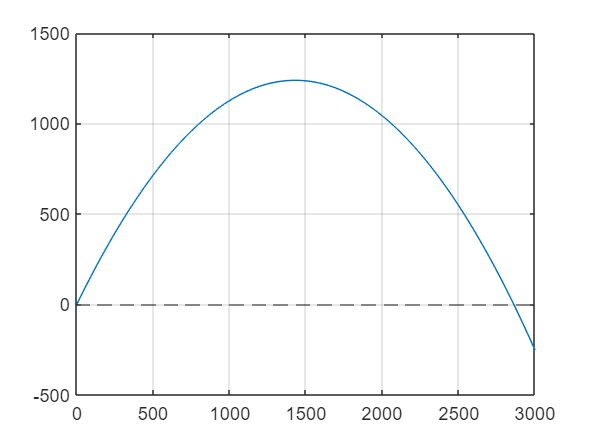


X_lin = linspace(0,3000,1000); 

plot(X_lin, y(X_lin)), yline(0, '--'), grid()

hold on

